# Fokker-Planck Equation using Spectral$$^*$$ Method

($$^*$$Technically it is **pseudo-spectral** method)

# Theory

We intend to solve the following linear partial differential equation, called the Fokker-Planck Equation: 


$$$$\frac{\partial \rho}{\partial t}=\nabla \cdot [(D\nabla\rho)+(\rho\nabla U)]\cdots(1)$$$$


This equation describes a system that undergoes diffusion, in the presence of a potential-which couples with the density field. Notice that, if $U=0$, our equation reduces to a diffusion equation. One can derive the above equation by consider a system of particles undergoing two competing processes, whilst conserving particle number :

- Individual particles undergo Brownian motion-Random Walk. 

- A potential trap- which causes the particles to clump(attractive potential) or scatter-off(repulsive potential)

### Derivation of Fokker-Planck:

Consider the derivation of the Fokker-Planck Equation from the points considered above:


$$$$\frac{\partial \rho}{\partial t}=-\nabla \cdot \vec{J}\cdots(2)\text{(Conserving Particle Number)}$$$$
      


$$$$J_{diff}=-D\nabla \rho\cdots \text{(Corresponding to Diffusion)}$$$$
  


$$$$J_{drift} = -\rho \nabla U\cdots \text{(Corresponding to Potential)}$$$$
 

Take, $J_{total}=J_{diff}+J_{drift}$, then substitute in eq(2), to obtain eq(1)

Intuitively, we can guess the steady state to be peaked around the minima of the potential. However, we can see it explicitly in 1D. 

In steady-state, we will want the $$\nabla \cdot J=0$$. Now, J can be 0 or constant(in 1D, we are not dealing with any curl or etc). Now, physically, J being constant is not physically a "steady state". So, we are left with the only option, $J_{total}=0$. We will arrive at $\rho=e^{-U/D}$ as the steady solution, which matches with our intuition.    

### Spectral Analysis:

Recall eq(1):


$$$$\frac{\partial \rho}{\partial t}=\nabla \cdot [(D\nabla\rho)+(\rho\nabla U)]\cdots(1)$$$$


Take the spatial fourier decomposition of $\rho$ , $U$ and consider $f(x)=\rho \nabla U$, and take the fourier decomposition of $f(x)$ accordingly. We will then obtain an ODE for each k-mode. Just like for the other cases we looked at, we numerically solve this by performing FFT, then solve the resultant ODE, and then finally do the inverse FFT and plot the result accordingly.

#   Code/Numerics

We will deal with one dimensional form of eq(1) for simplicity, which is


$$$\frac{\partial \rho}{\partial t}=\frac{\mathrm{d}}{\mathrm{d}x}\bigg[D\frac{\mathrm{d}\rho}{\mathrm{d}x}+\rho \frac{\mathrm{d}U}{\mathrm{d}x} \bigg]$$$



$$$$\frac{\mathrm{d}}{\mathrm{d}t}\tilde \rho=-Dk^2\tilde\rho+\iota k \tilde f; f=\rho \frac{\mathrm{d}U}{\mathrm{d}x}\cdots\text{(We obtained this by fourier transform)}$$ $$


## Algorithm

- Define the parameters,k-modes and initialize required variables properly

- Initialize the required functions and take the gradient of the potential

- Solve the resultant ODE using the for loop. within the same loop perform the fft of the the function $f$(because in the loop we update the value of $\rho$, and $f$ is dependent on it!)

## Defining Parameters

delt=0.1; % temporal resolution
delx=0.5; % spatial resolution
D=0.15; % diffusion constant
L=128;% no. of grid points (system size)
N=3000; % no. of iterations
x=1:L; % position vector

## Initializing Function(s) and Pre-solving

c0=exp(-((x)*delx).^2/100); % initial condition
c=c0;
cc=fft(c);
U=-cos(2*pi/L*(x-L/2)); % potential
Up=2*pi/L/delx*sin(2*pi/L*(x-L/2)); %gradient of the potential
K=2*pi/(L*delx)*[0:L/2-1,-L/2:-1]; % k modes
% K(L/2) = 0; % Explicitly zeroing the Nyquist frequency
cT = zeros(L,N); % To avoid Dynamic Memory Allocation- better efficiency

###  Note:

- We have a term $\displaystyle \iota k
$ in the fourier transformed differential equation, unlike the diffusion equation(where it did not care about the sign of k). Hence, putting the Nyquist term to 0 was essential. However, instructor did not, rather he defined it as `K=2*pi/(L*delx)*[0:L/2-1, 0,-L/2+1:-1];` which still worked, because in the end he used `c=real(ifft(cc))` which took care of the garbage imaginary value. 

- However, still, we are not explicitly putting the Nyquist term to 0, because it will cause the graph to be jagged[ Check it by running the code by uncommenting the `K(L/2) = 0` line !] However, why did this **"Spectral Ringing(Gibbs-Phenomenon)"** happen? 

- Even though zeroing the Nyquist term is "mathematically cleaner" for preventing imaginary numbers, it actually **reduces the resolution** of your grid slightly-zeroing out the Nyquist term, creates a **sharp truncation** in the frequency domain. From Fourier analysis, we know- **A sharp edge in frequency space creates ripples in physical space. **When a signal with steep gradients (like a Gaussian peak) is reconstructed after the sudden truncation of its high-frequency components, the resulting Fourier series cannot converge smoothly at the points of highest curvature(This is **Gibbs Phenomenon**)

- In the Pseudo-Spectral method(explained in next subsection!), point-wise multiplication in the spatial domain ($U' \cdot \rho$) is equivalent to a discrete convolution in the frequency domain. This convolution broadens the spectrum, transferring energy into high-frequency modes. By zeroing the Nyquist frequency, we truncated the bandwidth required to represent this energy transfer, leading to spectral ringing. Retaining the Nyquist mode allows the simulation to accommodate this spectral broadening, maintaining a smooth reconstruction of the density field.

## Solving the ODE

for i=1:N
    rho=Up.*c;
    crho=fft(rho);
    cc=cc+delt*(-D*K.^2.*cc+1i*K.*crho);
    c=real(ifft(cc));
    cT(:,i)=c;
end

### Note:

#### Why Pseudo-Spectral?

We are doing a point by point multiplication of `Up` and `c` and then doing the fourier transform of the product. This is totally in the spatial domain($O(L)$ complexity)-not in the frequency domain(`k`-space). According to the **Convolution Theorem**, a multiplication in space is a **convolution** in `k`-space. To multiply them without leaving `k`-space, every frequency of `U'` would have to interact with every frequency of `c`. For 128 points, that’s $128^2$ (**16,384 operations**). This is $O(L^2)$ complexity. We hence perform a pseudo-spectral method, where we multiply first in the spatial domain and then take the FT of the product

#### Aliasing effect caused by Pseudo-Spectral method

- When you multiply two signals together in the spatial domain, they **interact**. If $U'$ is a simple wave with frequency $k_1$ and $\rho$ is a wave with frequency $k_2$, their product doesn't just stay at those frequencies. It creates **new frequencies** that are the sum ($k_1 + k_2$) and the difference ($|k_1 - k_2|$) of the originals. As the density $\rho$ clumps into the narrow "well," it naturally becomes a "sharper" function. In Fourier terms, "sharper in space" means "wider in frequency." So, the product $U' \cdot \rho$ keeps producing higher and higher frequencies as the simulation progresses.

- Highest resolution on the grid is $k_{max} = \pi / \Delta x$. If $k_{\rho} + k_U > k_{max}$, the grid cannot represent this new high frequency. Instead of vanishing, this energy **aliases**—it "folds" back across the Nyquist limit and reappears as a low-frequency wave traveling in the *wrong* direction.

- These "ghost" frequencies can create small, un-physical oscillations (Wiggles) at the base of your density distribution. If these oscillations become large enough, they can lead to **negative density**, which is physically impossible.

#### Why Still does this work?

Using `c = real(ifft(cc))-`is essentially throwing away the "spectral trash" generated by the aliasing overlap(Mostly, it creates purely imaginary components in the $k$-space update.). While this keeps the code stable, a more advanced solver would prevent that trash from forming by using a larger $L$ or a filter.

## Plotting the Graph

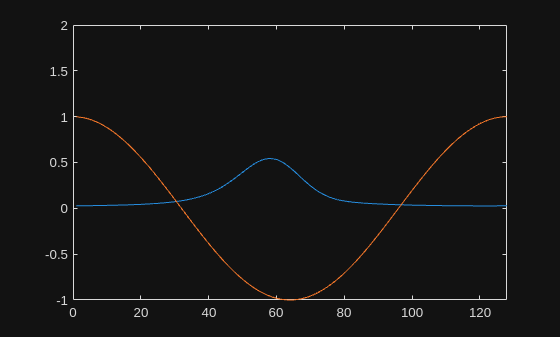

for i=1:20:N
     plot(x,cT(:,i),x,U);ylim([-1 2]);xlim([0 L]);
     pause(0.1);
end

# Miscellany

## Generating the GIF file

% --- Configuration ---
filename = 'FokkerPlanck_Evolution.gif';
if exist(filename, 'file'); delete(filename); end % Delete old version to avoid appending

% 1. Create a fixed-size figure (Standard web resolution)
h = figure('Units', 'pixels', 'Position', [100, 100, 600, 450]); 
ax = axes('Parent', h);

% 2. Initialize the Plot Handles
p_handle = plot(ax, x, cT(:,1), 'b', 'LineWidth', 2); hold(ax, 'on');
pot_handle = plot(ax, x, U, 'r--', 'LineWidth', 1.5); 

% 3. Static Formatting (Professional look for your site)
grid(ax, 'on');
ylim(ax, [-1.2 1.5]); xlim(ax, [1 L]);
xlabel(ax, 'Position (x)'); ylabel('Density \rho / Potential U');
legend(ax, 'Density Field', 'Potential Well');

% 4. Animation and File Writing
step_size = 50; 
for i = 1:step_size:N
    % Update the Blue Line data
    set(p_handle, 'YData', cT(:,i)); 
    title(ax, ['Iteration: ', num2str(i)]);
    drawnow; % Refreshes the Live Script view
    
    % Capture the figure as an image
    frame = getframe(h);
    im = frame2im(frame);
    [imind, cm] = rgb2ind(im, 256);
    
    % Write to the actual .gif file on your hard drive
    if i == 1
        imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.03); 
    else
        imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.03);
    end
end
close(h); % Close the figure when done